## Acinetobacter Data

From Magenta supplementary dataset

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'acinetobacter_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_acinetobacter_orthologs.xlsx';
trainingData = 'indigo';

summaryTable = 1×11 table
      min       median       max      range       mean        std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    _______    ________    _______    ______    ________    _______    ________________    ____________    _______________    _______________    __________

    -2.2746    -0.23072    0.61829    2.8929    -0.29397    0.61135           45                23               12                false          0.15091  


drugList = 6×1 cell array
    {'AMK'}
    {'AMP'}
    {'AZM'}
    {'NAL'}
    {'RIF'}
    {'TET'}


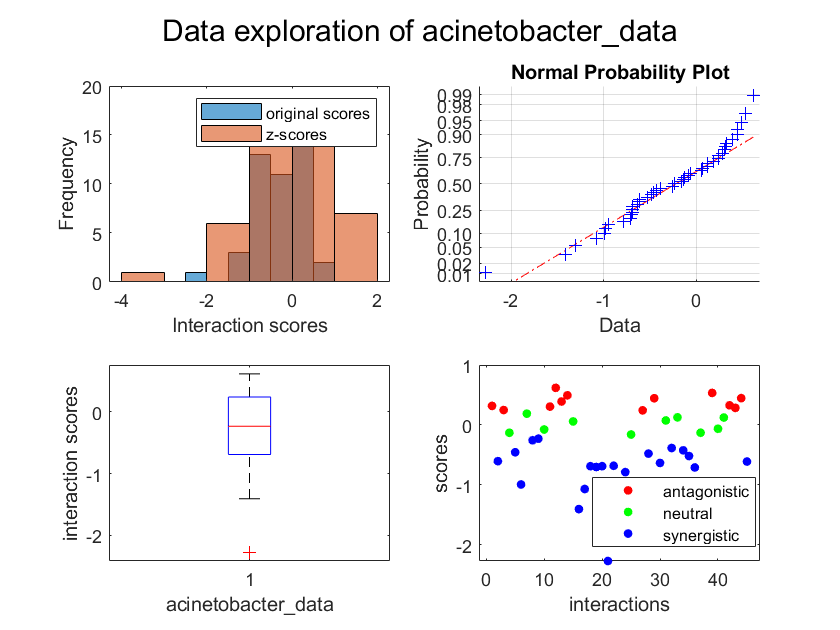

[summary,drugList] = dataExplore(testFile);

files = dataFiles();
compareFiles = [{testFile};{files.indigoData}];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    acinetobacter_data score    orig_ecoli score
    ______    ______    ________________________    ________________

    "AMK"     "NAL"              0.24682                 0.7145     
    "AMK"     "RIF"             -0.13242                 1.0995     
    "AMK"     "TET"             -0.45847                 0.7785     
    "NAL"     "RIF"              0.38991                  0.437     
    "NAL"     "TET"              0.49292                  3.158     
    "RIF"     "TET"             0.056965                 -0.252     
    "AMK"     "NAL"             -0.69083                 0.7145     
    "AMK"     "RIF"             -0.70375                 1.0995     


interactionCounts = 2×2 table
                          acinetobacter_data    orig_ecoli
                          __________________    __________

    acinetobacter_data            0                 18    
    orig_ecoli                    0                  0    


R_values = 2×2 table
                          acinetobacter_data    orig_ecoli
                          __________________    __________

    acinetobacter_data            0               0.3041  
    orig_ecoli                    0                    0  


P_values = 2×2 table
                          acinetobacter_data    orig_ecoli
                          __________________    __________

    acinetobacter_data            0              0.21987  
    orig_ecoli                    0                    0  


indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData);

Run 1
Elapsed time is 59.660793 seconds.
Run 2
Elapsed time is 24.820882 seconds.
Run 3
Elapsed time is 23.923308 seconds.
Run 4
Elapsed time is 26.195060 seconds.
Run 5
Elapsed time is 35.327942 seconds.


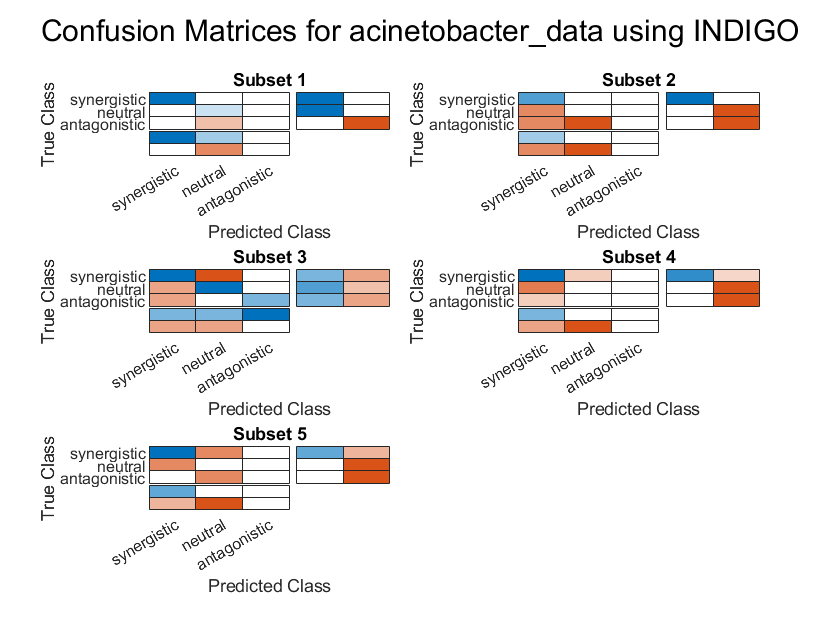

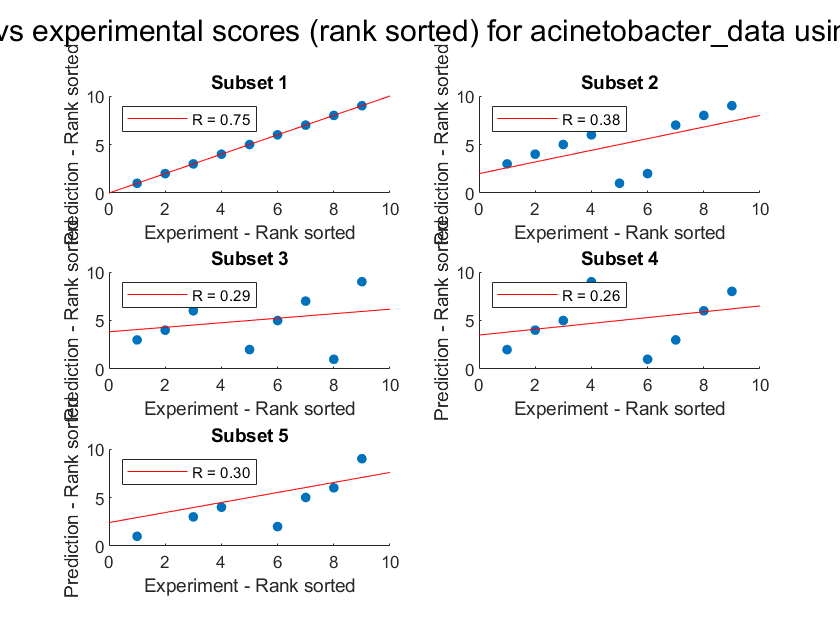

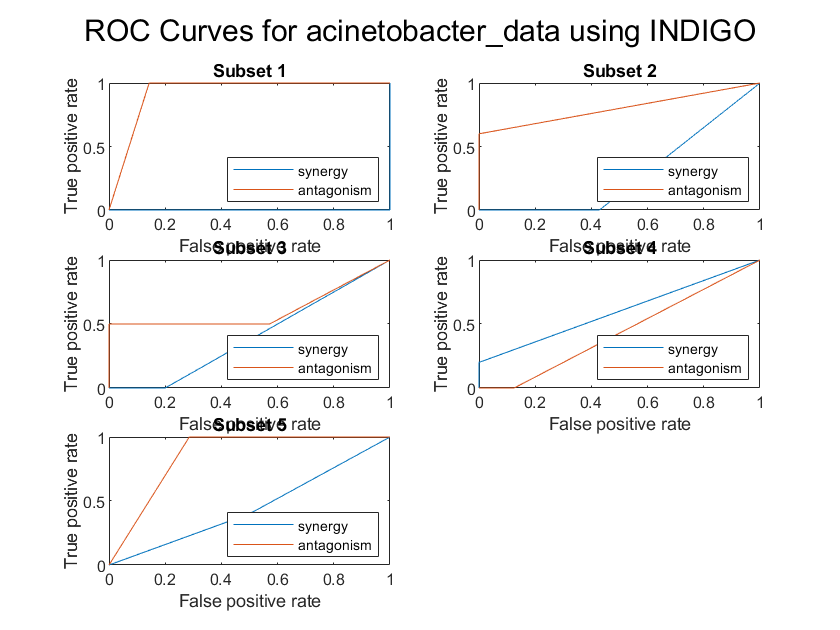

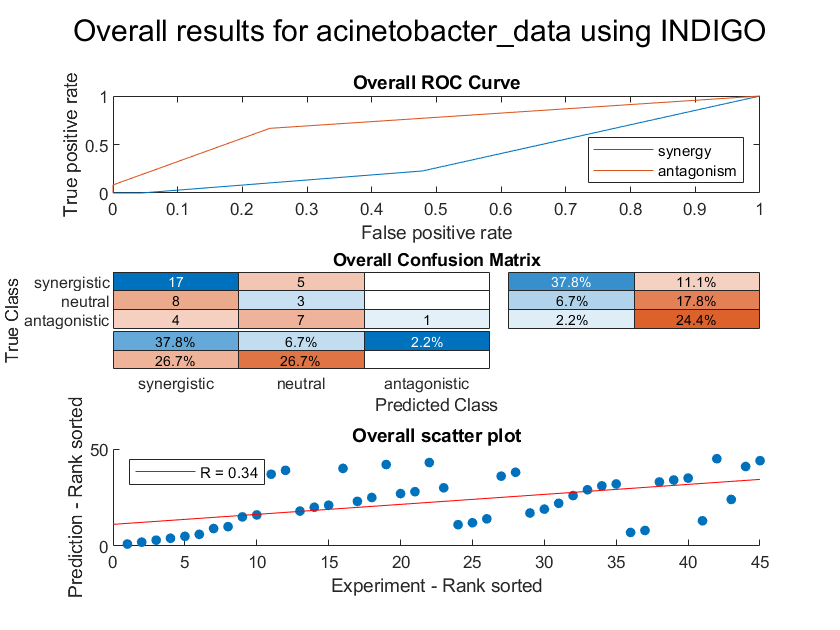

resultsTable = 5×12 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          0.75382       

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.39678
    P value                     0.34384
    Accuracy                    0.46667
    Absolute error              0.62222
    Precision (synergy)         0.58667
    Recall (synergy)               0.78
    Precision (antagonism)          NaN
    Recall (antagonism)             0.1
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.34714
    AUC - ROC (antagonism)      0.72607


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      45
    R (rank)                     0.34347
    P value                     0.020889
    Accuracy                     0.46667
    Absolute error               0.62222
    Precision (synergy)          0.58621
    Recall (synergy)             0.77273
    Precision (antagonism)             1
    Recall (antagonism)         0.083333
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.36957
    AUC - ROC (antagonism)       0.72222


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'acinetobacter_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_acinetobacter_orthologs.xlsx';
trainingData = 'indigo';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 55.564248 seconds.
Run 2
Elapsed time is 50.168472 seconds.
Run 3
Elapsed time is 40.195358 seconds.
Run 4
Elapsed time is 58.303383 seconds.
Run 5
Elapsed time is 61.243514 seconds.


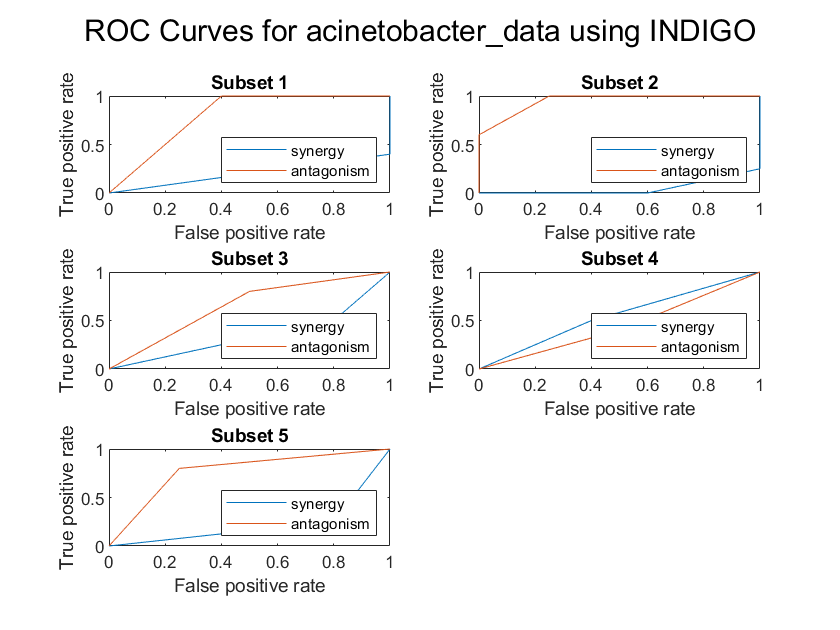

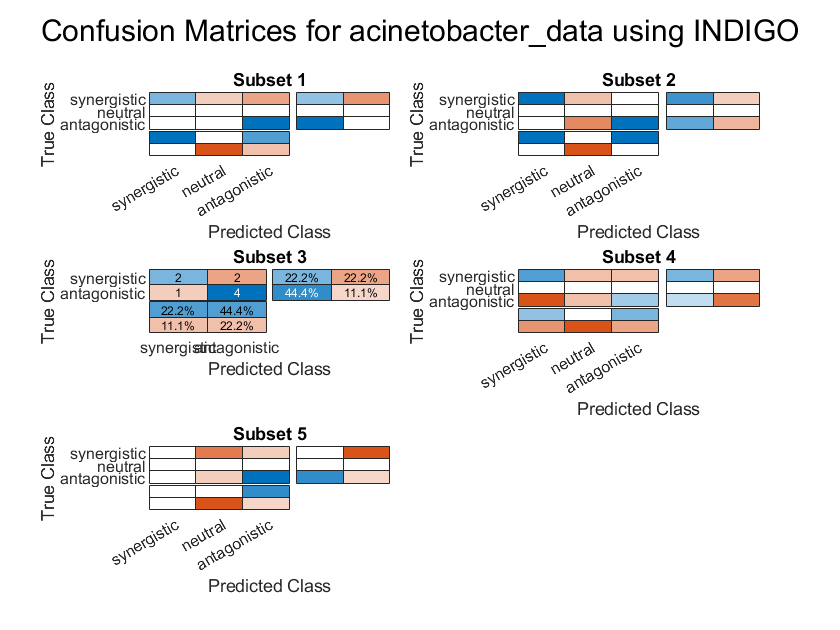

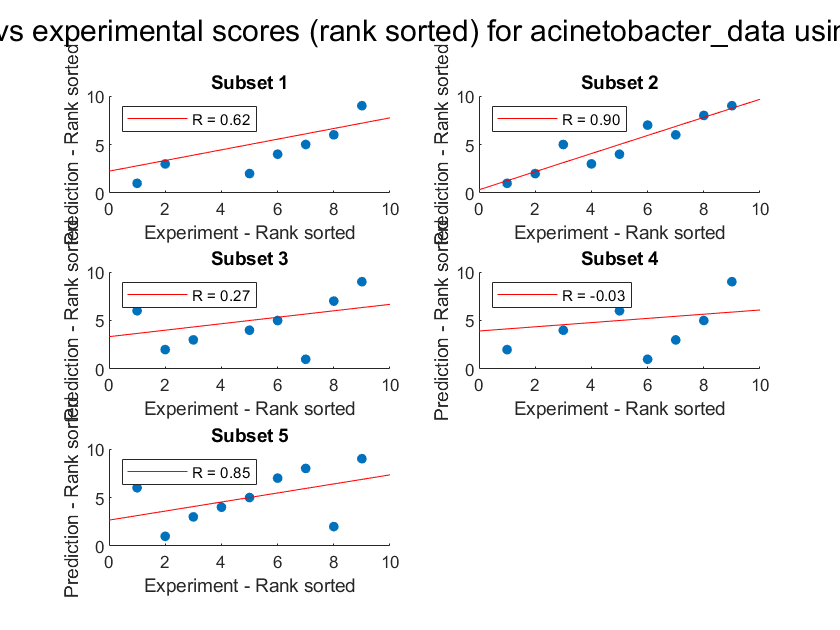

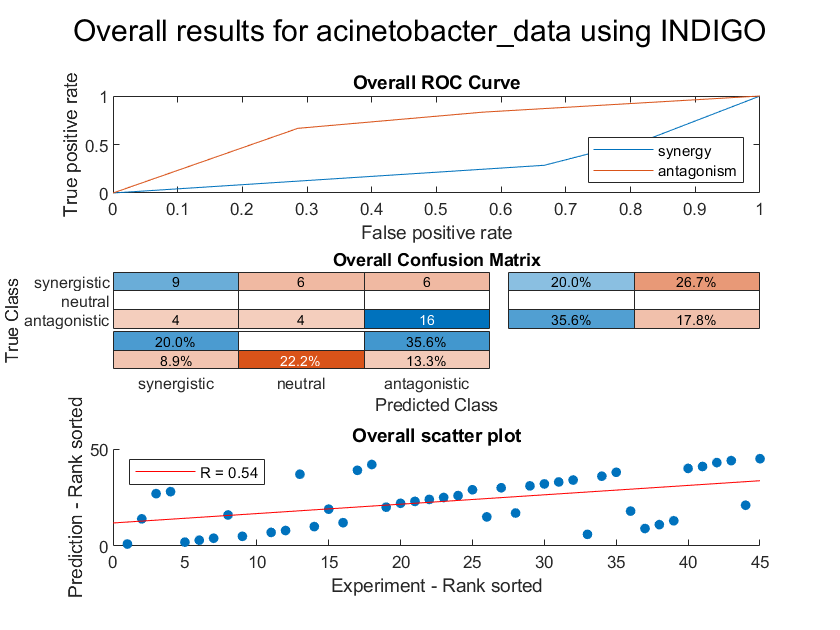

resultsTable = 5×12 table
                Interactions    R (rank)      P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    _________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9            0.6192

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.52053
    P value                      0.3017
    Accuracy                    0.55556
    Absolute error              0.66667
    Precision (synergy)             NaN
    Recall (synergy)               0.43
    Precision (antagonism)      0.72667
    Recall (antagonism)            0.68
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)           0.275
    AUC - ROC (antagonism)        0.725


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        45
    R (rank)                       0.53886
    P value                     0.00013403
    Accuracy                       0.55556
    Absolute error                 0.66667
    Precision (synergy)            0.69231
    Recall (synergy)               0.42857
    Precision (antagonism)         0.72727
    Recall (antagonism)            0.66667
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.29762
    AUC - ROC (antagonism)         0.70238


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'acinetobacter_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_acinetobacter_orthologs.xlsx';
trainingData = 'nature';
standardize = '';

files = dataFiles();
compareFiles = [testFile;files.natureData];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter_data score    ecoli_bw25113 score
    ______    ______    ________________________    ___________________

    "AMK"     "AZM"             -0.60698                  0.20244      
    "AMK"     "RIF"             -0.13242                  0.25778      
    "AMK"     "AZM"              -1.0719                  0.20244      
    "AMK"     "RIF"             -0.70375                  0.25778      
    "AMK"     "AZM"             -0.38683                  0.20244      
    "AMK"     "RIF"              -0.4258                  0.25778      


sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter_data score    ecoli_iAi1 score
    ______    ______    ________________________    ________________

    "AMK"     "AZM"             -0.60698                0.039346    
    "AMK"     "RIF"             -0.13242               -0.069498    
    "AMK"     "AZM"              -1.0719                0.039346    
    "AMK"     "RIF"             -0.70375               -0.069498    
    "AMK"     "AZM"             -0.38683                0.039346    
    "AMK"     "RIF"              -0.4258               -0.069498    


acinetobacter_data and stlt2 have no shared interactions

acinetobacter_data and st14028 have no shared interactions



sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter_data score    pao1 score
    ______    ______    ________________________    __________

    "AMK"     "AZM"             -0.60698             0.68877  
    "AMK"     "RIF"             -0.13242             0.15255  
    "AMK"     "AZM"              -1.0719             0.68877  
    "AMK"     "RIF"             -0.70375             0.15255  
    "AMK"     "AZM"             -0.38683             0.68877  
    "AMK"     "RIF"              -0.4258             0.15255  


sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter_data score    pa14 score
    ______    ______    ________________________    __________

    "AMK"     "AZM"             -0.60698             0.40503  
    "AMK"     "RIF"             -0.13242             0.17758  
    "AMK"     "AZM"              -1.0719             0.40503  
    "AMK"     "RIF"             -0.70375             0.17758  
    "AMK"     "AZM"             -0.38683             0.40503  
    "AMK"     "RIF"              -0.4258             0.17758  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    ecoli_iAi1 score
    ______    ______    ___________________    ________________

    "A22"     "ATM"          -0.11682              -0.23949    
    "A22"     "BLM"          -0.18842              -0.22326    
    "A22"     "MMC"          -0.15416              0.081189    
    "A22"     "PUR"           0.10034               0.10767    
    "A22"     "PYO"           0.28322             -0.082868    
    "A22"     "RIF"          0.099699               0.17919    
    "AMK"     "AZM"           0.20244              0.039346    
    "AMK"     "BZK"           0.40112              0.082268    


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    stlt2 score
    ______    ______    ___________________    ___________

    "A22"     "MMC"           -0.15416           0.19836  
    "AMK"     "BZK"            0.40112           0.29453  
    "AMK"     "EGCG"           0.13458           0.13635  
    "AMK"     "ERI"            0.20099           0.15979  
    "AMK"     "LCX"          -0.044191          -0.36433  
    "AMK"     "PMS"            0.48777           0.31997  
    "AMK"     "PRC"            0.47286           0.19732  
    "AMK"     "PUR"           -0.42117          -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    st14028 score
    ______    ______    ___________________    _____________

    "A22"     "MMC"           -0.15416            0.046942  
    "AMK"     "BZK"            0.40112             0.28743  
    "AMK"     "EGCG"           0.13458            0.023459  
    "AMK"     "ERI"            0.20099           -0.035934  
    "AMK"     "LCX"          -0.044191            -0.42079  
    "AMK"     "PMS"            0.48777            -0.11198  
    "AMK"     "PRC"            0.47286            0.076645  
    "AMK"     "PUR"           -0.42117           -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pao1 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           0.040284 
    "A22"     "MMC"          -0.15416          -0.099203 
    "AMK"     "AZM"           0.20244            0.68877 
    "AMK"     "EGCG"          0.13458            0.14272 
    "AMK"     "ERI"           0.20099            0.28607 
    "AMK"     "MMC"           -0.2502           0.062727 
    "AMK"     "NIT"          -0.21472            0.22065 
    "AMK"     "PRC"           0.47286            0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pa14 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           -0.11745 
    "A22"     "MMC"          -0.15416            0.27324 
    "AMK"     "AZM"           0.20244            0.40503 
    "AMK"     "EGCG"          0.13458           0.083746 
    "AMK"     "ERI"           0.20099            0.20578 
    "AMK"     "MMC"           -0.2502            0.12617 
    "AMK"     "NIT"          -0.21472          -0.052538 
    "AMK"     "PRC"           0.47286             0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    stlt2 score
    ______    ______    ________________    ___________

    "A22"     "MMC"         0.081189          0.19836  
    "AMK"     "BZK"         0.082268          0.29453  
    "AMK"     "EGCG"        0.034852          0.13635  
    "AMK"     "ERI"         0.047723          0.15979  
    "AMK"     "LCX"          -0.1704         -0.36433  
    "AMK"     "PMS"         0.048965          0.31997  
    "AMK"     "PRC"         0.059603          0.19732  
    "AMK"     "PUR"         -0.26455         -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    st14028 score
    ______    ______    ________________    _____________

    "A22"     "MMC"         0.081189           0.046942  
    "AMK"     "BZK"         0.082268            0.28743  
    "AMK"     "EGCG"        0.034852           0.023459  
    "AMK"     "ERI"         0.047723          -0.035934  
    "AMK"     "LCX"          -0.1704           -0.42079  
    "AMK"     "PMS"         0.048965           -0.11198  
    "AMK"     "PRC"         0.059603           0.076645  
    "AMK"     "PUR"         -0.26455          -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pao1 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         0.040284 
    "A22"     "MMC"         0.081189        -0.099203 
    "AMK"     "AZM"         0.039346          0.68877 
    "AMK"     "EGCG"        0.034852          0.14272 
    "AMK"     "ERI"         0.047723          0.28607 
    "AMK"     "MMC"         -0.11537         0.062727 
    "AMK"     "NIT"         -0.30784          0.22065 
    "AMK"     "PRC"         0.059603          0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pa14 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         -0.11745 
    "A22"     "MMC"         0.081189          0.27324 
    "AMK"     "AZM"         0.039346          0.40503 
    "AMK"     "EGCG"        0.034852         0.083746 
    "AMK"     "ERI"         0.047723          0.20578 
    "AMK"     "MMC"         -0.11537          0.12617 
    "AMK"     "NIT"         -0.30784        -0.052538 
    "AMK"     "PRC"         0.059603           0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    st14028 score
    ______    ______    ___________    _____________

    "A22"     "GEN"       0.12582          0.16781  
    "A22"     "MMC"       0.19836         0.046942  
    "AMK"     "ATM"      -0.30991         -0.14214  
    "AMK"     "BZK"       0.29453          0.28743  
    "AMK"     "CEC"      -0.11493         -0.16492  
    "AMK"     "EGCG"      0.13635         0.023459  
    "AMK"     "ERI"       0.15979        -0.035934  
    "AMK"     "LCX"      -0.36433         -0.42079  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pao1 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836     -0.099203 
    "AMK"     "ATM"       -0.30991      -0.32109 
    "AMK"     "EGCG"       0.13635       0.14272 
    "AMK"     "ERI"        0.15979       0.28607 
    "AMK"     "PRC"        0.19732       0.19014 
    "AMK"     "TOB"       -0.33487      -0.13132 
    "AMX"     "AMK"        -0.1155      -0.19518 
    "AMX"     "CIP"      -0.047861      0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pa14 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836       0.27324 
    "AMK"     "ATM"       -0.30991      -0.50344 
    "AMK"     "EGCG"       0.13635      0.083746 
    "AMK"     "ERI"        0.15979       0.20578 
    "AMK"     "PRC"        0.19732        0.1142 
    "AMK"     "TOB"       -0.33487      -0.12544 
    "AMX"     "AMK"        -0.1155       -0.2228 
    "AMX"     "CIP"      -0.047861        0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pao1 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942      -0.099203 
    "AMK"     "ATM"        -0.14214       -0.32109 
    "AMK"     "EGCG"       0.023459        0.14272 
    "AMK"     "ERI"       -0.035934        0.28607 
    "AMK"     "PRC"        0.076645        0.19014 
    "AMK"     "TOB"        -0.10058       -0.13132 
    "AMX"     "AMK"          -0.145       -0.19518 
    "AMX"     "CIP"         0.22995       0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pa14 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942        0.27324 
    "AMK"     "ATM"        -0.14214       -0.50344 
    "AMK"     "EGCG"       0.023459       0.083746 
    "AMK"     "ERI"       -0.035934        0.20578 
    "AMK"     "PRC"        0.076645         0.1142 
    "AMK"     "TOB"        -0.10058       -0.12544 
    "AMX"     "AMK"          -0.145        -0.2228 
    "AMX"     "CIP"         0.22995         0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    pao1 score    pa14 score
    ______    ______    __________    __________

    "AMK"     "A22"      0.030386      -0.15949 
    "AMX"     "A22"      0.047543      -0.13341 
    "CHL"     "A22"      0.046395       0.10396 
    "DOX"     "A22"      -0.03145        0.1363 
    "FOF"     "A22"      0.049735      -0.59174 
    "NIT"     "A22"      0.033376       0.14544 
    "PRC"     "A22"      0.042237       0.20696 
    "AMX"     "AMK"      -0.19518       -0.2228 


interactionCounts = 7×7 table
                          acinetobacter_data    ecoli_bw25113    ecoli_iAi1    stlt2    st14028    pao1    pa14
                          __________________    _____________    __________    _____    _______    ____    ____

    acinetobacter_data            0                   6               6           0         0        6       6 
    ecoli_bw25113                 0                   0             316         148       148       72      72 
    ecoli_iAi1                    0                   0               0         148       148       72      72 
    stlt2                         0                   0               0           0       248       53 

R_values = 7×7 table
                          acinetobacter_data    ecoli_bw25113    ecoli_iAi1    stlt2     st14028      pao1        pa14  
                          __________________    _____________    __________    ______    _______    ________    ________

    acinetobacter_data            0                0.29277        -0.29277          0          0    -0.29277    -0.29277
    ecoli_bw25113                 0                      0         0.64896      0.745    0.67384     0.24449     0.39303
    ecoli_iAi1                    0                      0               0     0.6407    0.64464    0.081516      0.3926
    stlt2                         0                      0         

P_values = 7×7 table
                          acinetobacter_data    ecoli_bw25113    ecoli_iAi1    stlt2    st14028       pao1          pa14   
                          __________________    _____________    __________    _____    _______    __________    __________

    acinetobacter_data            0                  0.7            0.7          0         0              0.7           0.7
    ecoli_bw25113                 0                    0              0          0         0         0.038725    0.00063738
    ecoli_iAi1                    0                    0              0          0         0           0.4952    0.00064705
    stlt2                         0                 

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData);

Run 1
Elapsed time is 287.380207 seconds.
Run 2
Elapsed time is 325.781332 seconds.
Run 3
Elapsed time is 294.503748 seconds.
Run 4
Elapsed time is 283.153485 seconds.
Run 5
Elapsed time is 225.815904 seconds.


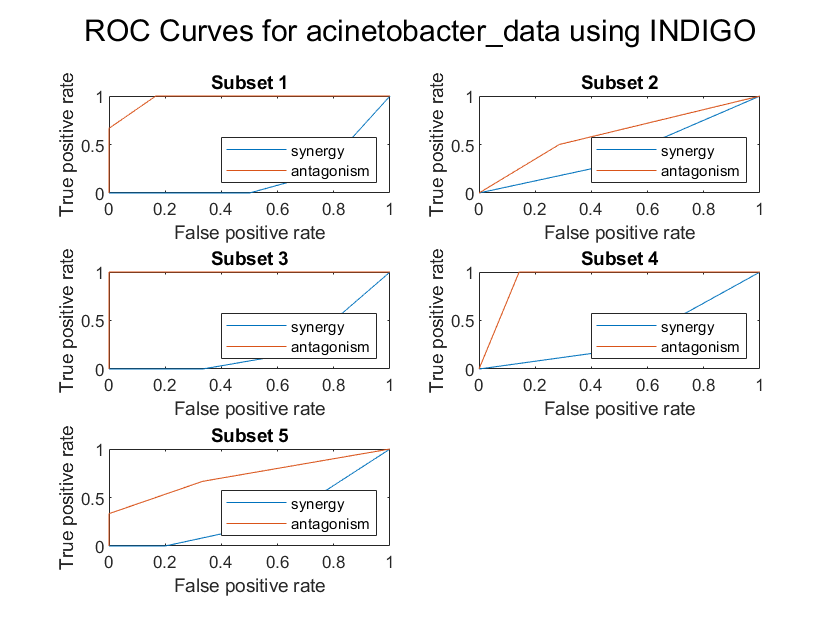

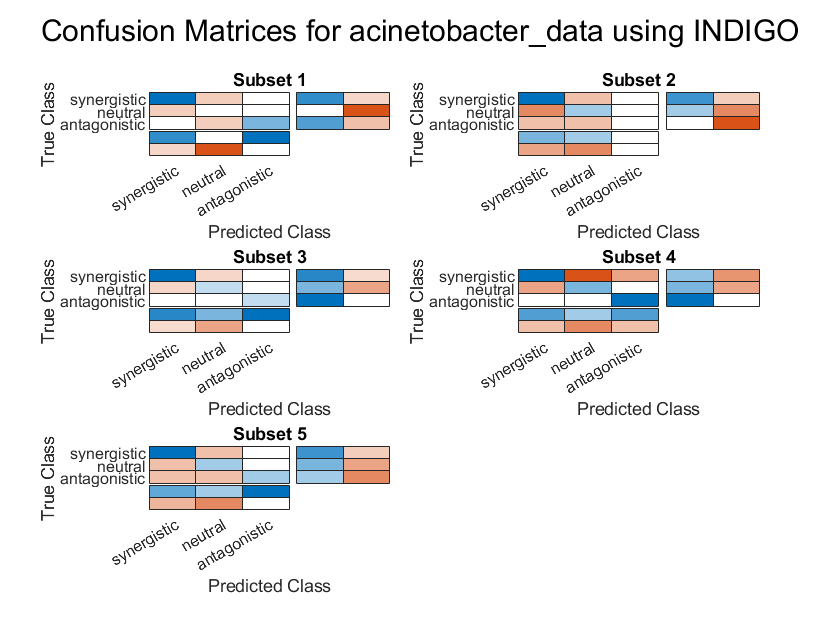

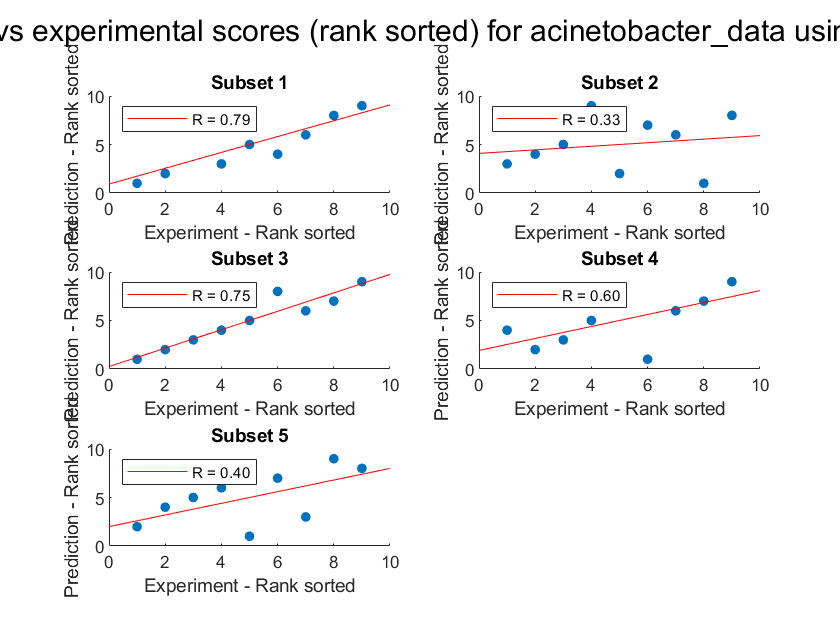

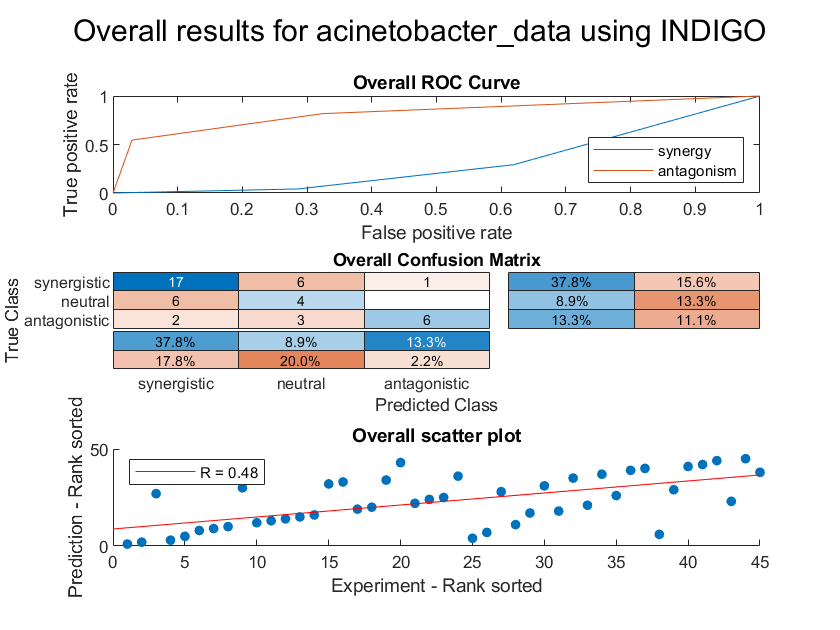

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          0.78994     

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.57404
    P value                     0.16204
    Accuracy                        0.6
    Absolute error              0.46667
    Precision (synergy)            0.68
    Recall (synergy)            0.70667
    Precision (antagonism)          NaN
    Recall (antagonism)             0.6
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.29444
    AUC - ROC (antagonism)      0.84603


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        45
    R (rank)                       0.47871
    P value                     0.00087954
    Accuracy                           0.6
    Absolute error                 0.46667
    Precision (synergy)               0.68
    Recall (synergy)               0.70833
    Precision (antagonism)         0.85714
    Recall (antagonism)            0.54545
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.30754
    AUC - ROC (antagonism)         0.82353


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'acinetobacter_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_acinetobacter_orthologs.xlsx';
trainingData = 'nature';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 78.064728 seconds.
Run 2
Elapsed time is 146.222842 seconds.
Run 3
Elapsed time is 137.472420 seconds.
Run 4
Elapsed time is 86.010876 seconds.
Run 5
Elapsed time is 104.379985 seconds.


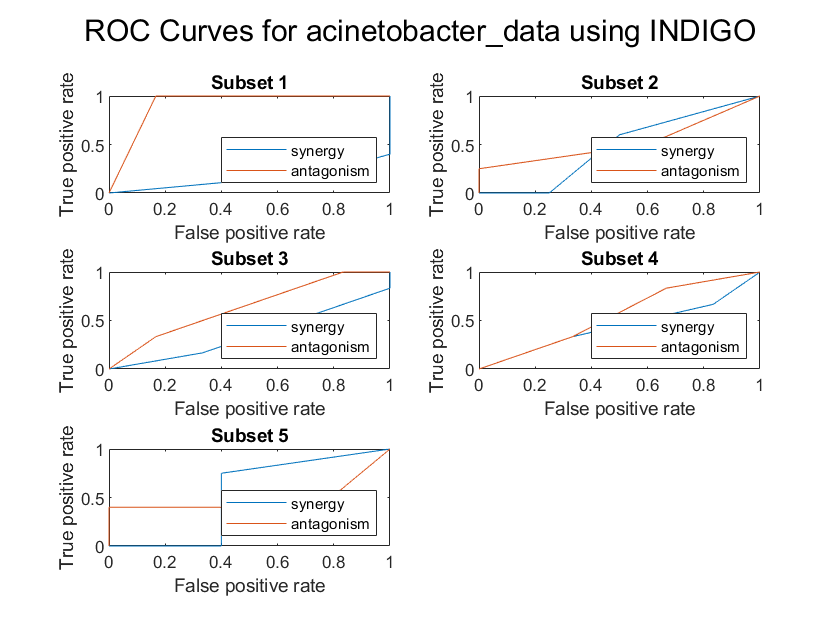

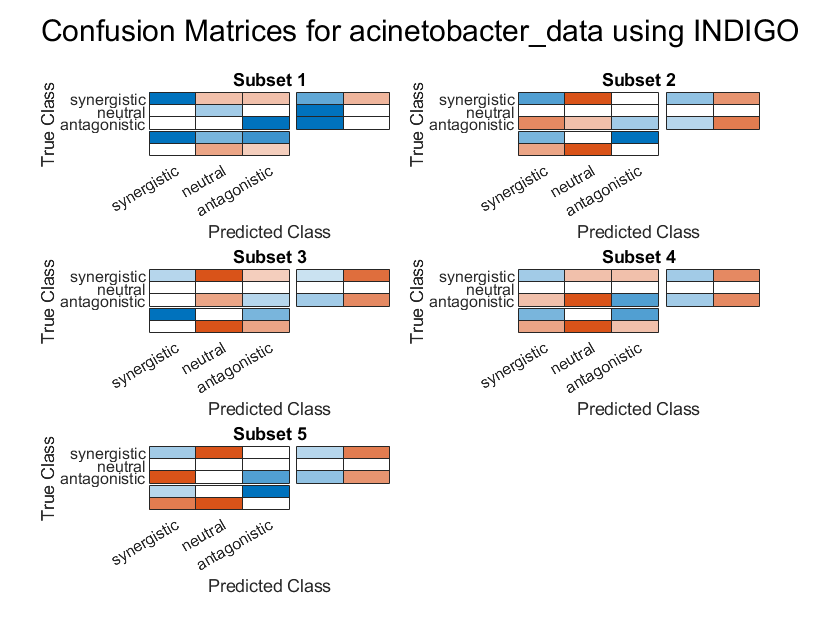

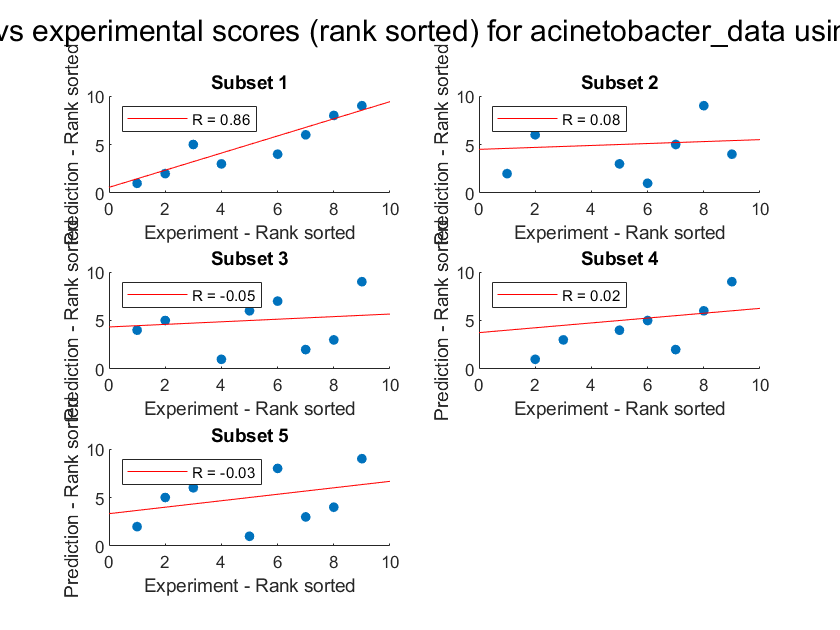

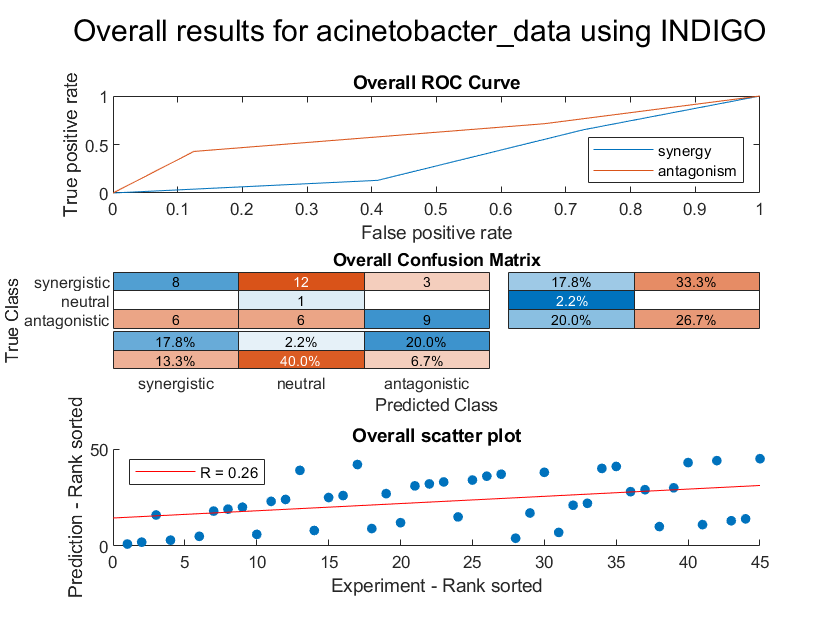

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    _________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9            0.86083 

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.17534
    P value                     0.73201
    Accuracy                        0.4
    Absolute error                  0.8
    Precision (synergy)            0.65
    Recall (synergy)               0.35
    Precision (antagonism)      0.78333
    Recall (antagonism)         0.46333
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.39111
    AUC - ROC (antagonism)      0.62222


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      45
    R (rank)                     0.26205
    P value                     0.082043
    Accuracy                         0.4
    Absolute error                   0.8
    Precision (synergy)          0.57143
    Recall (synergy)             0.34783
    Precision (antagonism)          0.75
    Recall (antagonism)          0.42857
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.37648
    AUC - ROC (antagonism)       0.62202


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'acinetobacter_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_acinetobacter_orthologs.xlsx';
trainingData = 'nature_ecoli';
standardize = '';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData);

Run 1
Elapsed time is 6.770745 seconds.
Run 2
Elapsed time is 6.517723 seconds.
Run 3
Elapsed time is 6.533937 seconds.
Run 4
Elapsed time is 6.600637 seconds.
Run 5
Elapsed time is 6.628637 seconds.


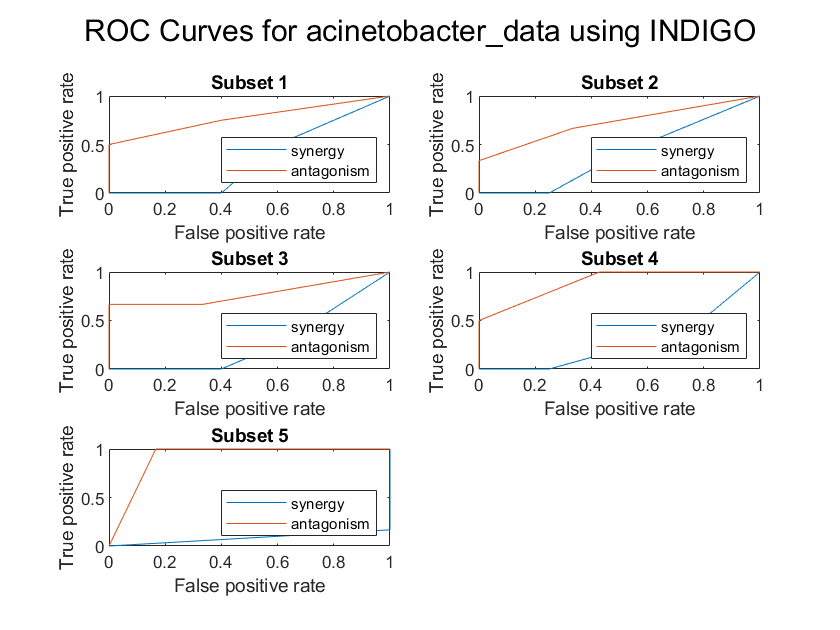

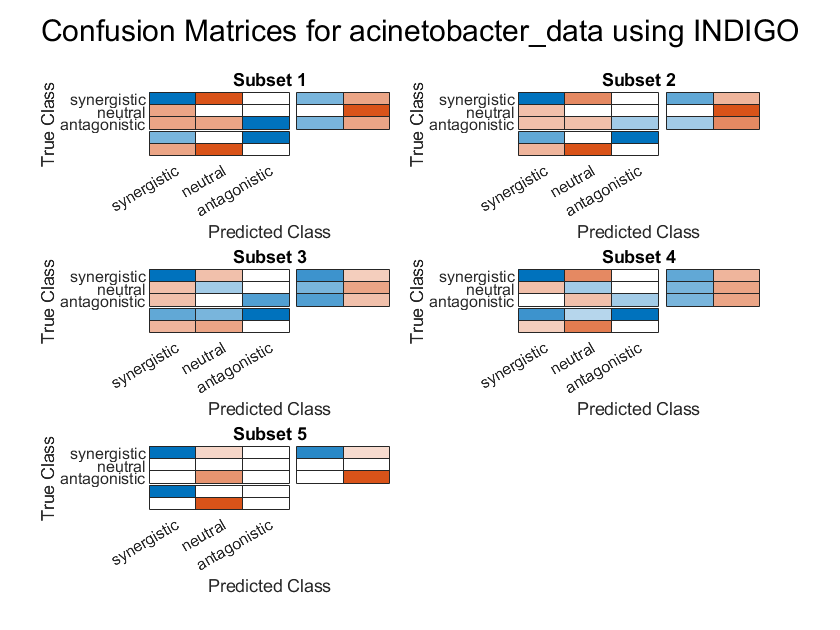

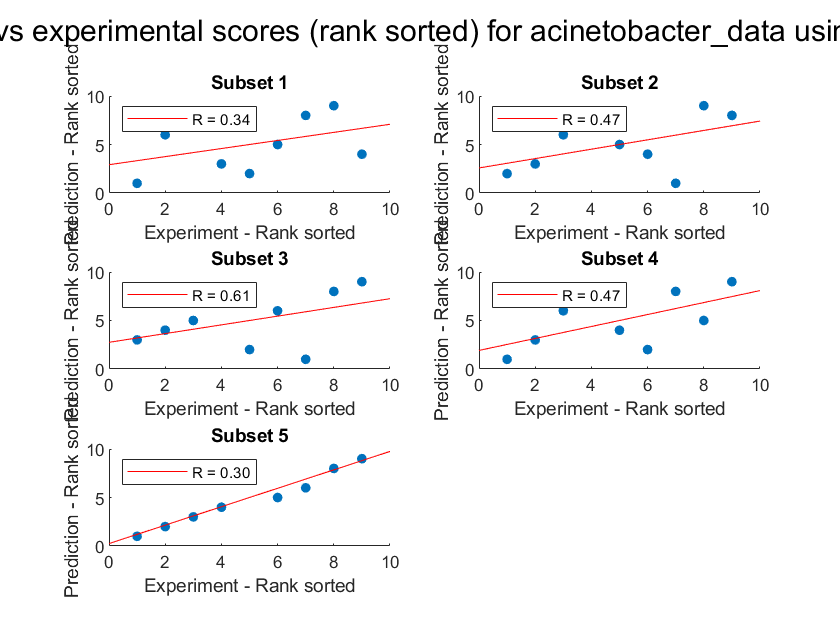

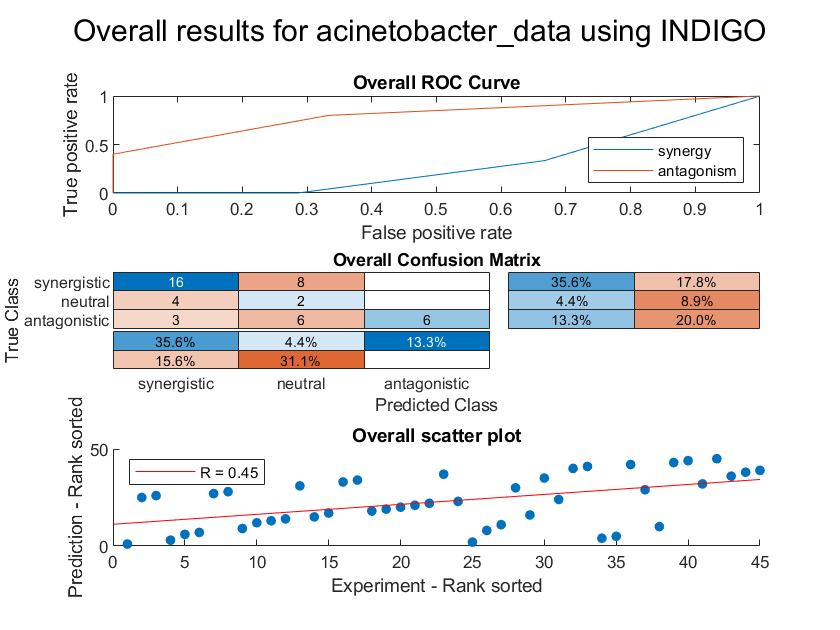

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          0.33615     

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.43566
    P value                     0.26446
    Accuracy                    0.53333
    Absolute error              0.53333
    Precision (synergy)            0.69
    Recall (synergy)            0.65667
    Precision (antagonism)          NaN
    Recall (antagonism)             0.4
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.27667
    AUC - ROC (antagonism)       0.8169


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       45
    R (rank)                      0.45146
    P value                     0.0018532
    Accuracy                      0.53333
    Absolute error                0.53333
    Precision (synergy)           0.69565
    Recall (synergy)              0.66667
    Precision (antagonism)              1
    Recall (antagonism)               0.4
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.28571
    AUC - ROC (antagonism)            0.8


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'acinetobacter_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_acinetobacter_orthologs.xlsx';
trainingData = 'nature_ecoli';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 8.522632 seconds.
Run 2
Elapsed time is 11.724687 seconds.
Run 3
Elapsed time is 8.208822 seconds.
Run 4
Elapsed time is 8.483792 seconds.
Run 5
Elapsed time is 8.250083 seconds.


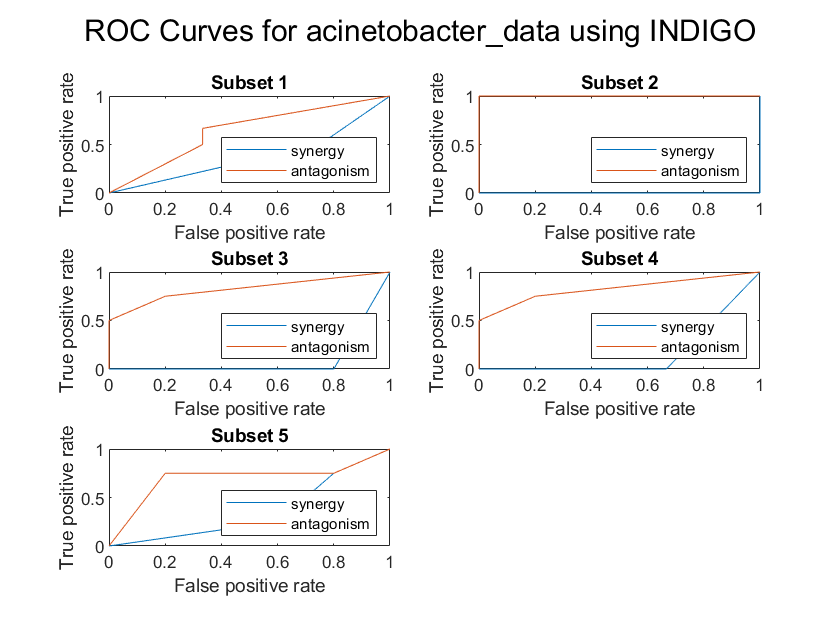

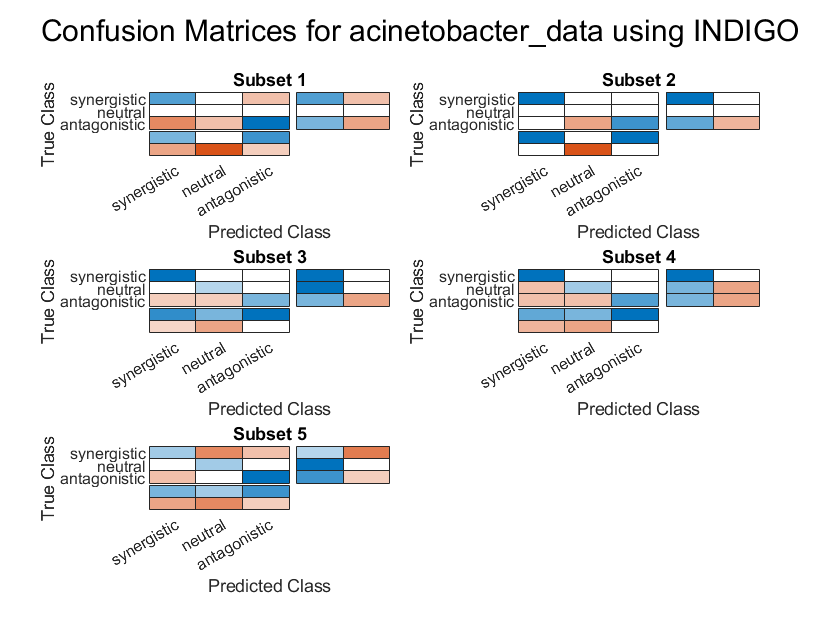

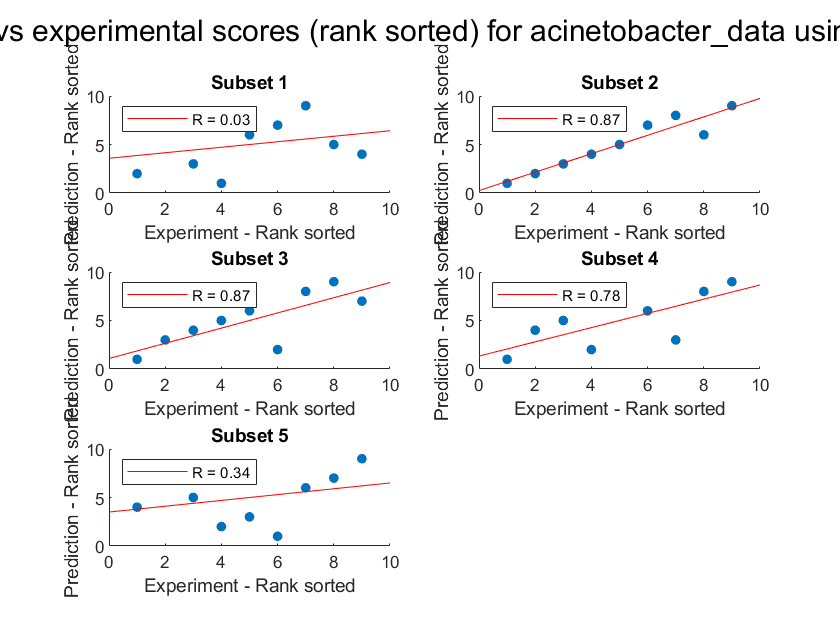

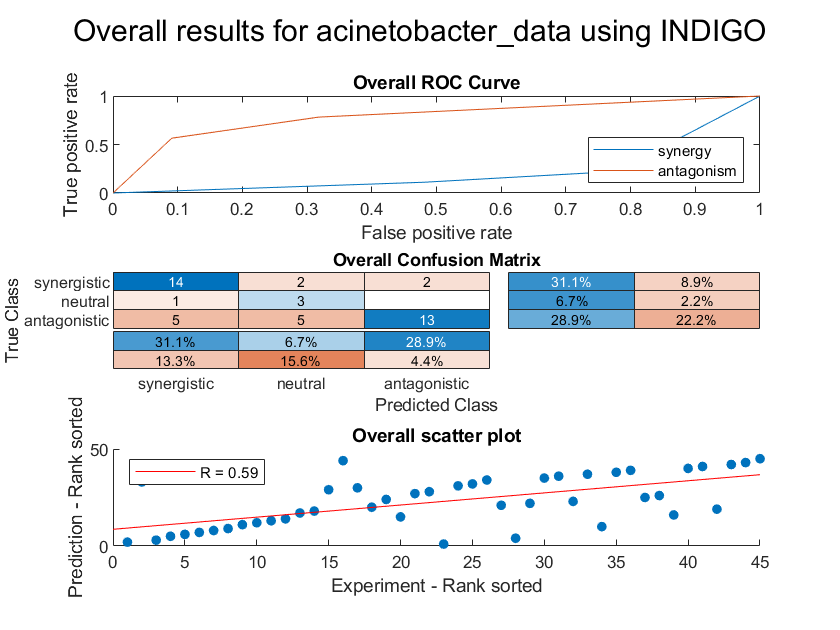

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          0.033333  

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.57979
    P value                     0.26777
    Accuracy                    0.66667
    Absolute error              0.48889
    Precision (synergy)            0.68
    Recall (synergy)            0.78333
    Precision (antagonism)          0.9
    Recall (antagonism)            0.57
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.19556
    AUC - ROC (antagonism)      0.79778


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        45
    R (rank)                       0.59298
    P value                     1.7681e-05
    Accuracy                       0.66667
    Absolute error                 0.48889
    Precision (synergy)                0.7
    Recall (synergy)               0.77778
    Precision (antagonism)         0.86667
    Recall (antagonism)            0.56522
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.21193
    AUC - ROC (antagonism)         0.78656


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))